robot = importrobot("universalUR5.urdf")

robot =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base_link'  'base'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'ee_link'  'tool0'}
      BaseName: 'world'
       Gravity: [0 0 0]
    DataFormat: 'struct'


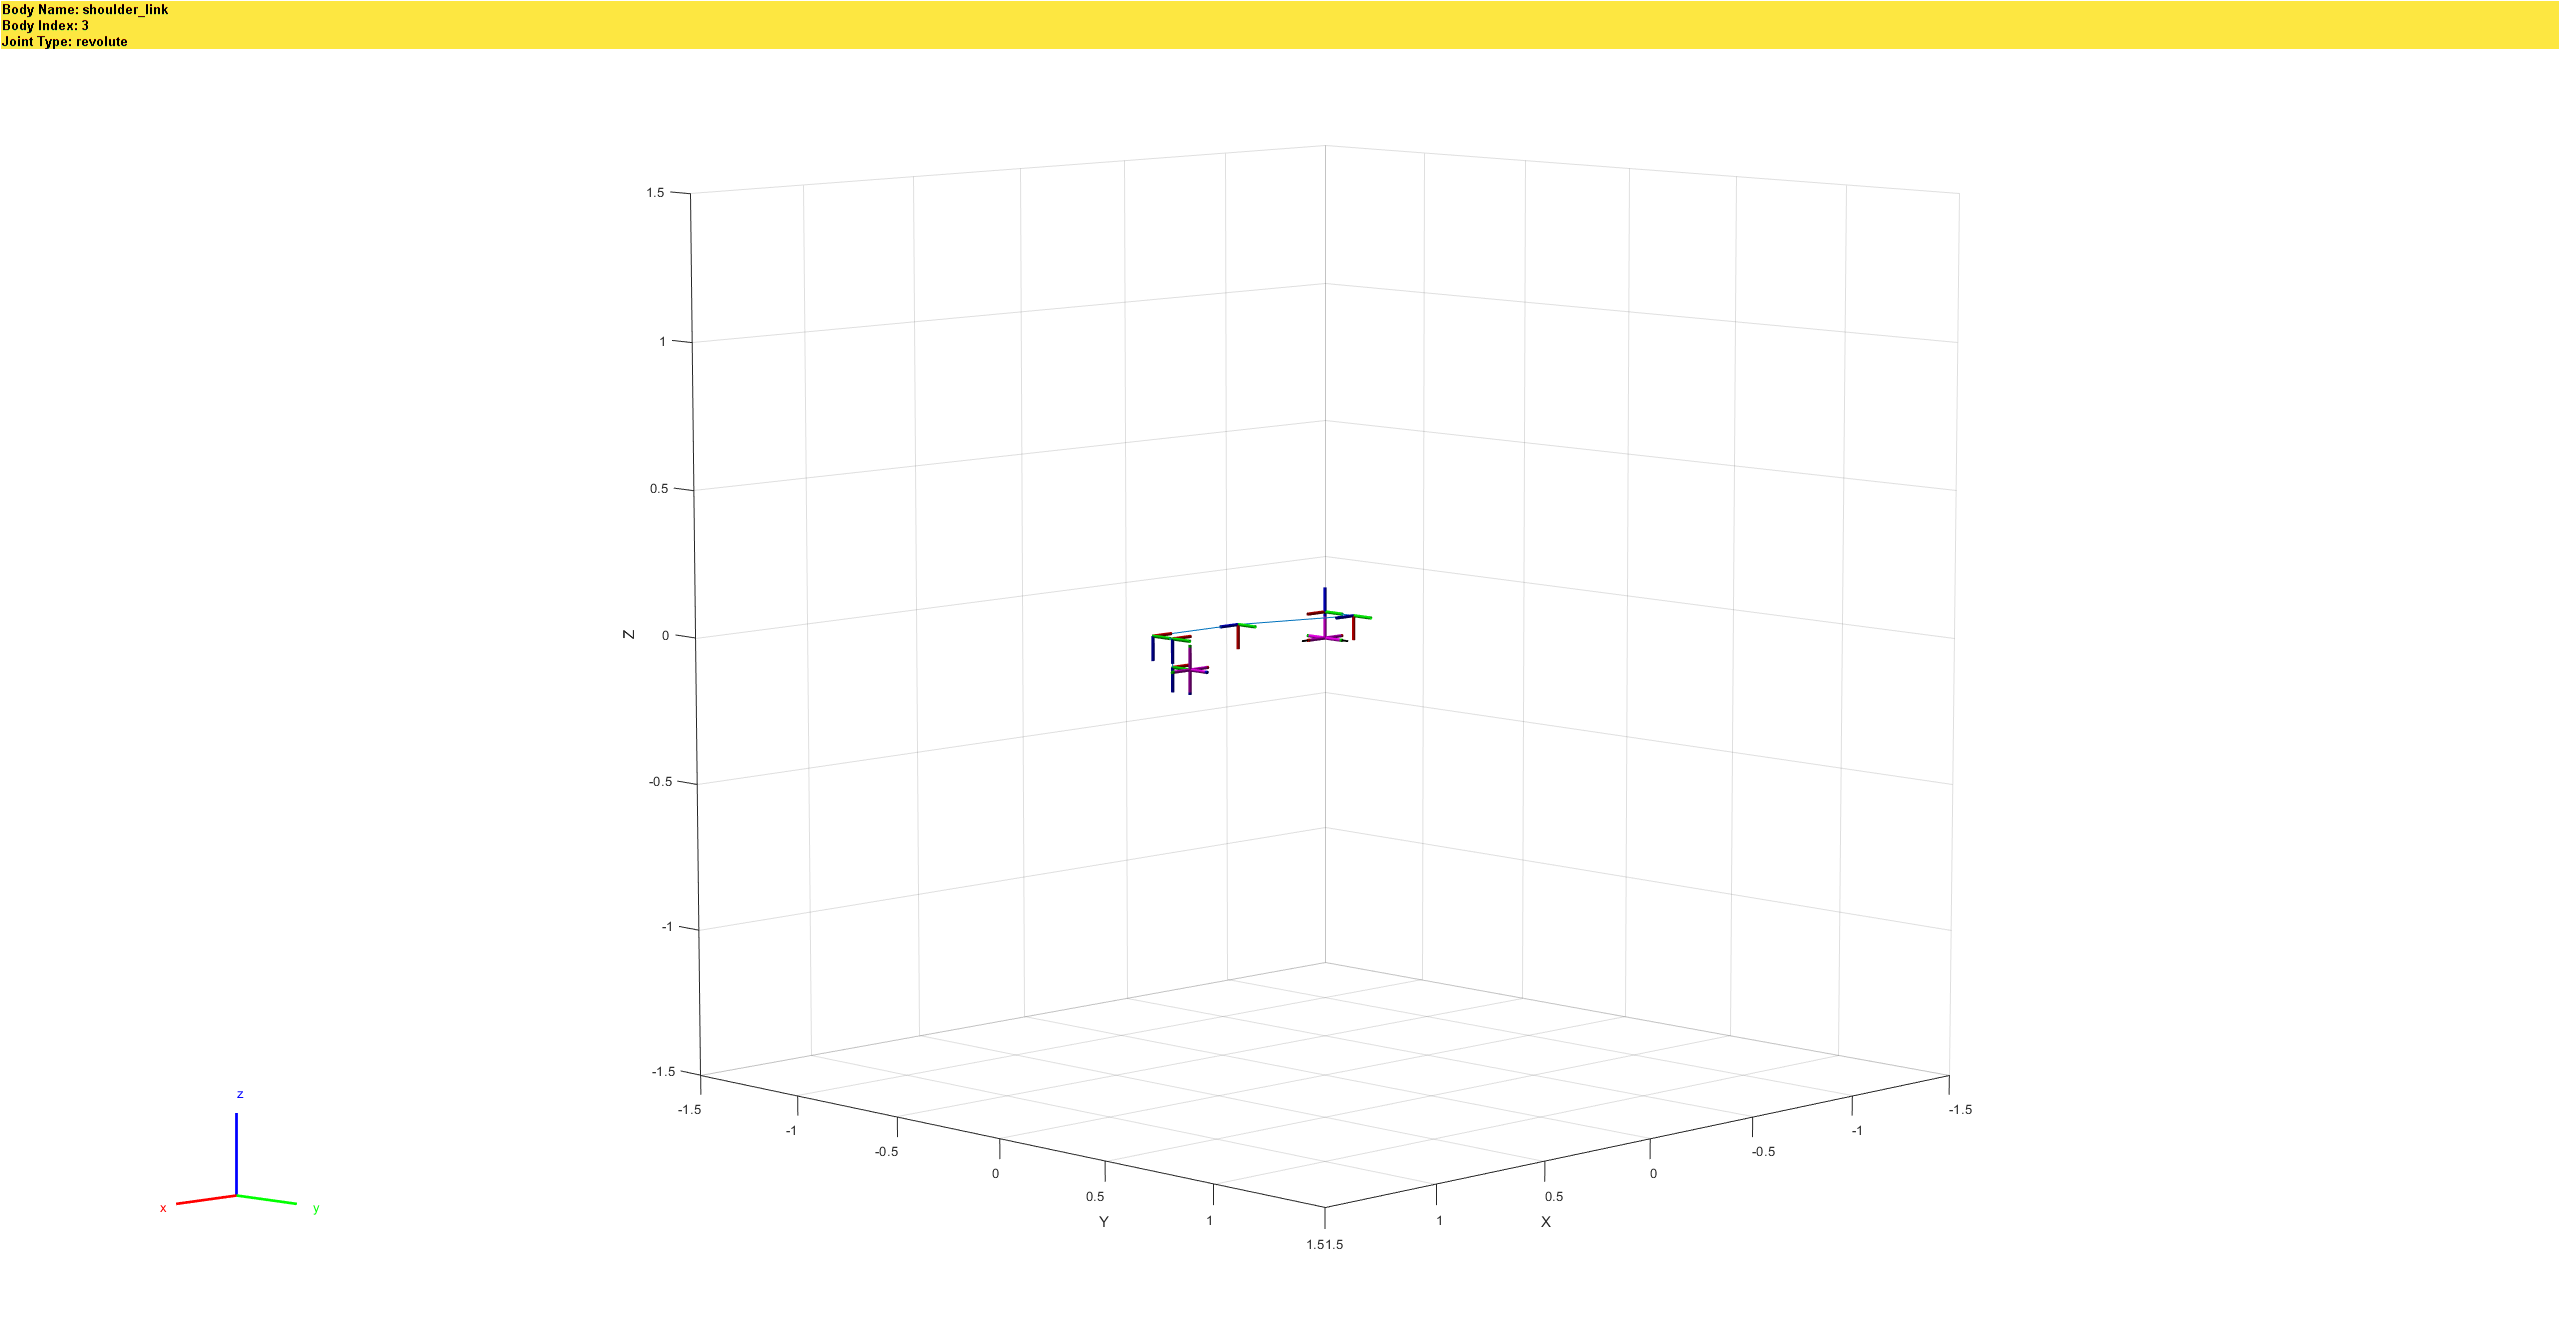

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



show(robot, "Visuals","off")

%show(robot)

for i = 1:robot.NumBodies
    robot.Bodies{i}.Name
    robot.Bodies{i}.Joint.JointToParentTransform
end

ans = 'base_link'

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


ans = 'base'

ans =    -1.0000   -0.0000         0         0
    0.0000   -1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


ans = 'shoulder_link'

ans =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000    0.0892
         0         0         0    1.0000


ans = 'upper_arm_link'

ans =     0.0000         0    1.0000         0
         0    1.0000         0    0.1358
   -1.0000         0    0.0000         0
         0         0         0    1.0000


ans = 'forearm_link'

ans =     1.0000         0         0         0
         0    1.0000         0   -0.1197
         0         0    1.0000    0.4250
         0         0         0    1.0000


ans = 'wrist_1_link'

ans =     0.0000         0    1.0000         0
         0    1.0000         0         0
   -1.0000         0    0.0000    0.3922
         0         0         0    1.0000


ans = 'wrist_2_link'

ans =     1.0000         0         0         0
         0    1.0000         0    0.0930
         0         0    1.0000         0
         0         0         0    1.0000


ans = 'wrist_3_link'

ans =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000    0.0946
         0         0         0    1.0000


ans = 'ee_link'

ans =     0.0000   -1.0000         0         0
    1.0000    0.0000         0    0.0823
         0         0    1.0000         0
         0         0         0    1.0000


ans = 'tool0'

ans =     1.0000         0         0         0
         0    0.0000    1.0000    0.0823
         0   -1.0000    0.0000         0
         0         0         0    1.0000



zv = [0;0;0];
ex = [1;0;0];
ey = [0;1;0];
ez = [0;0;1];

kin.H = [ez ey ey ey -ez ey];
kin.P = [0.089159*ez, 0.1358*ey, -0.1197*ey+0.425*ex, 0.3922*ex, 0.093*ey, -0.0946*ez, 0.0823*ey];
kin.joint_type = zeros([6 1]);

Pick a joint configuration find the associated end effector pose

q_true = rand([6 1])*2*pi - pi

q_true =     1.4446
   -0.8426
    0.0640
   -1.5153
    0.4843
   -0.2039


[R_0T, p_0T] = fwdkin(kin, q_true)

R_0T =     0.3610   -0.9167   -0.1710
   -0.7769   -0.1942   -0.5989
    0.5158    0.3491   -0.7823


p_0T =    -0.1040
    0.6257
    0.7732
